close all
clear

Exercise 3

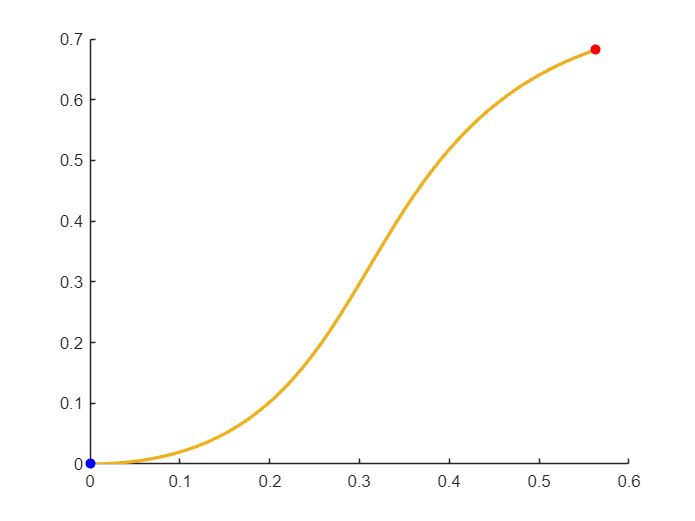

% Variables initialization
syms s

q_i = [0 0 0]';
x_i = q_i(1);
y_i = q_i(2);
theta_i = q_i(3);

q_f = rand(1, 3)';
q_f = q_f/norm(q_f);
x_f = q_f(1);
y_f = q_f(2);
theta_f = q_f(3);

k = 1;

t_i = 0;
t_f = 3;
t_c = 0.05;
t = t_i:t_c:t_f;

% Coefficients of the Cartesian polynomial path
alpha_x = k*cos(theta_f)-3*x_f;
alpha_y = k*sin(theta_f)-3*y_f;
beta_x = k*cos(theta_i)+3*x_i;
beta_y = k*sin(theta_i)+3*y_i;

%Cartesian polynomial path
x_s = s.^3.*x_f - (s-1).^3.*x_i + alpha_x.*s.^2.*(s-1) + beta_x.*s.*(s-1).^2;
y_s = s.^3.*y_f - (s-1).^3.*y_i + alpha_y.*s.^2.*(s-1) + beta_y.*s.*(s-1).^2;
xd_s = diff(x_s);
xdd_s = diff(xd_s);
yd_s = diff(y_s);
ydd_s = diff(yd_s);

% Trapezoidal velocity profile
%[s,sd,sdd,tSamples,pp] = trapveltraj([0 1],t_f/t_c)

% Cubic velocity profile
[s,sd,sdd,pp] = cubicpolytraj([0 1],[t_i t_f],t);

% Computation of vel and angular vel
v_tilde = subs(sqrt(xd_s.^2+yd_s.^2), s=s);
v = v_tilde.*sd;
omega_tilde = subs((ydd_s.*xd_s-xdd_s.*yd_s)./(xd_s.^2+yd_s.^2), s=s);
omega = omega_tilde.*sd;

% Sub of the symbolic repr 
x_d = subs(x_s, s=s);
xd_d = subs(xd_s, s=s);
y_d = subs(y_s, s=s);
yd_d = subs(yd_s, s=s);

% Path plot
hold on
plot(x_d , y_d, 'LineWidth', 2, 'Color', [0.9290 0.6940 0.1250]);
scatter(x_i, y_i, "filled", "b");
scatter(x_f, y_f, "filled", "r");

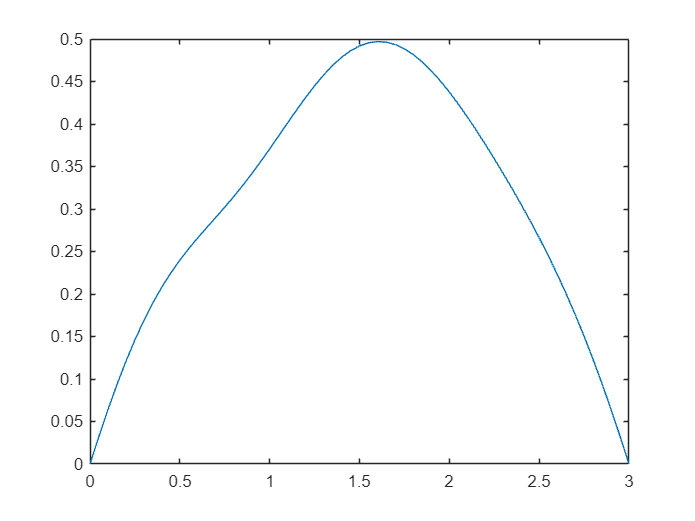


% Vel plot
figure()
plot(t, v);

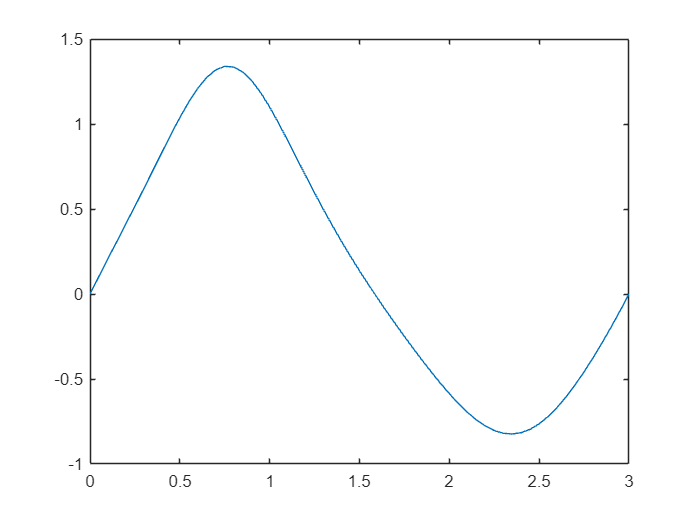


% Angular vel plot
figure()
plot(t, omega)

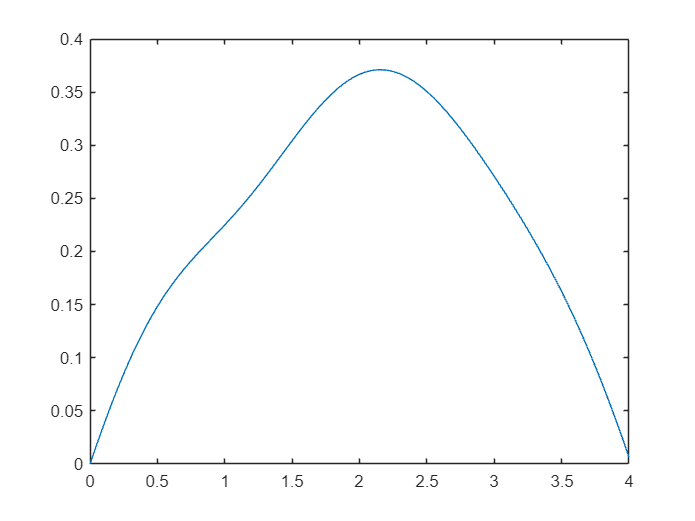

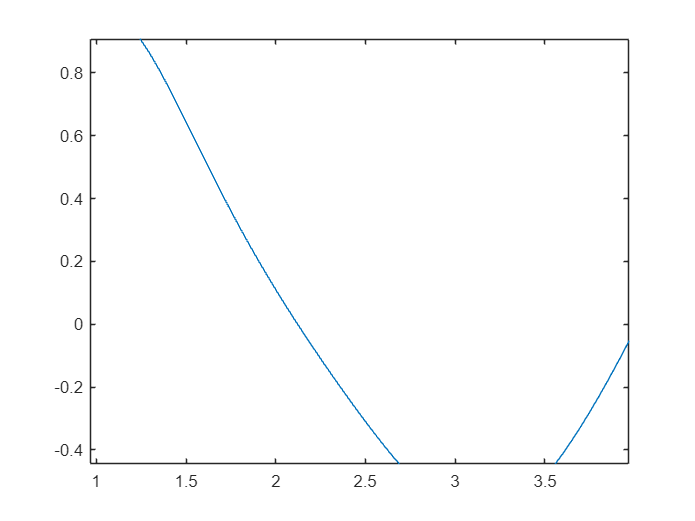


% MAXIMUM VALUES
max_vel = 2;
max_omega = 1;

% Time scaling
if(abs(max(omega))>max_omega || abs(max(v))>max_vel)
    % Scaling factor
    k = double(max(max(abs(omega))/max_omega, max(abs(v))/max_vel));

    t_f = t_f*k;
    t = t_i:t_c:t_f;

    % New vel profile
    [s,sd,sdd,pp] = cubicpolytraj([0 1],[t_i t_f],t);
    v_tilde = subs(sqrt(xd_s.^2+yd_s.^2), s=s);
    v = v_tilde.*sd;
    omega_tilde = subs((ydd_s.*xd_s-xdd_s.*yd_s)./(xd_s.^2+yd_s.^2), s=s);
    omega = omega_tilde.*sd;

    % Plots
    figure()
    plot(t, v);
    figure()
    plot(t, omega)

end

Exercise 4

% Variables initialization
b = 0.01;
K_1 = 7;
K_2 = 7;

x = subs(x_s, s=s);
xd = subs(xd_s, s=s);
y = subs(y_s, s=s);
yd = subs(yd_s, s=s);
theta = atan2(yd, xd);

y_1 = x + b.*cos(theta);
y_1_dot = v.*cos(theta) - omega.*b.*sin(theta);
y_2 = y + b.*sin(theta);
y_2_dot = v.*sin(theta) + omega.*b.*cos(theta);

x_d = timeseries(double(x), t);
y_d = timeseries(double(y), t);
theta = timeseries(double(theta), t);
y_1_d = timeseries(double(y_1), t);
y_2_d = timeseries(double(y_2), t);
y_1_dot_d = timeseries(double(y_1_dot), t);
y_2_dot_d = timeseries(double(y_2_dot), t);

y_1_end = double(y_1(end));
y_2_end = double(y_2(end));
y_1_dot_end = double(y_1_dot(end));
y_2_dot_end = double(y_2_dot(end));
